# Homework 10

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1.)

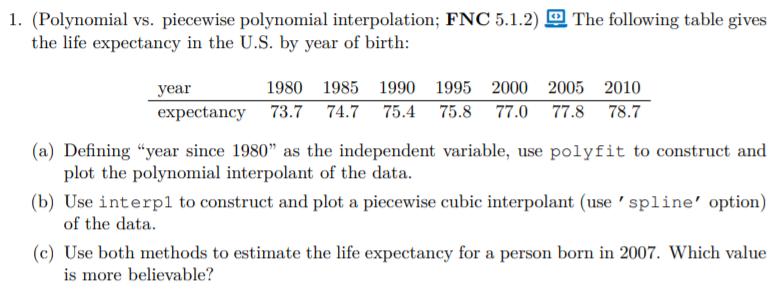

### Part a.)

xdp = [1980 1985 1990 1995 2000 2005 2010]-1980;
ydp = [73.7 74.7 75.4 75.8 77.0 77.8 78.7];
c = polyfit(xdp, ydp, length(xdp)-1);
p = @(x) polyval(c, x);

clf
plot(xdp, ydp, 'o')
grid on, hold on
fplot(p, [1980 2010]-1980)
title('Life Expectancy in the US by year of Birth using Polynomial Interpolant')
xlabel('Years since 1980')
ylabel('Life Expectancy')

### Part b.)

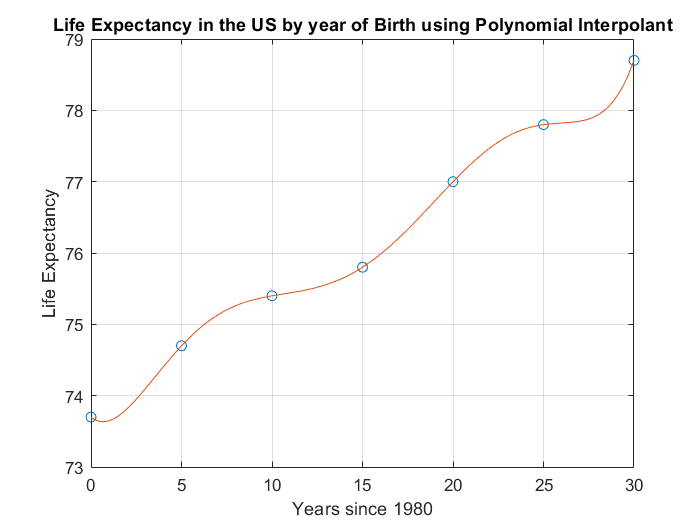

hold off

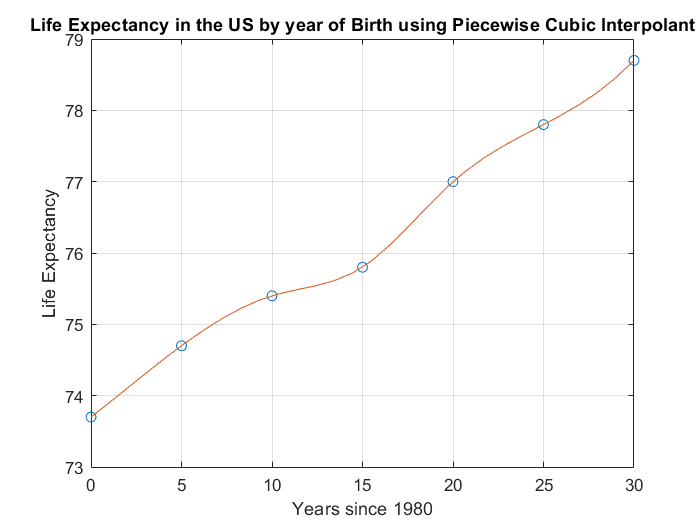

clf
x = linspace(1980,2010,30)-1980;
plot(xdp, ydp, 'o')
grid on, hold on
plot(x, interp1(xdp, ydp, x, 'spline'))
title('Life Expectancy in the US by year of Birth using Piecewise Cubic Interpolant')
xlabel('Years since 1980')
ylabel('Life Expectancy')

### Part c.)

Polyat2007 = p(27)

Polyat2007 = 77.8475

Cubicat2007 = interp1(xdp, ydp, 27, 'spline')

Cubicat2007 = 78.0842

The data from the cubic polynomial is more believable at it follows a much smoother graph that has less dips while the polynomial interpolant is much less stable as you get closer to the endpoints of the graph from Runge's phenomenon which is why there are weird oscilations around the endpoints. Because of this we know that data is a little less reliable versus the cubic interpolant that has a much smoother graph with less oscilations.

## Problem 2.)

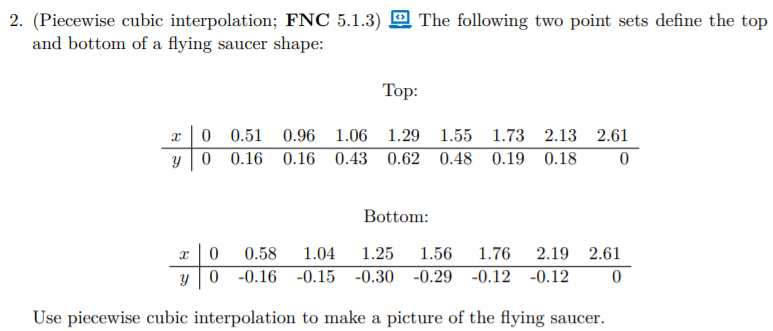

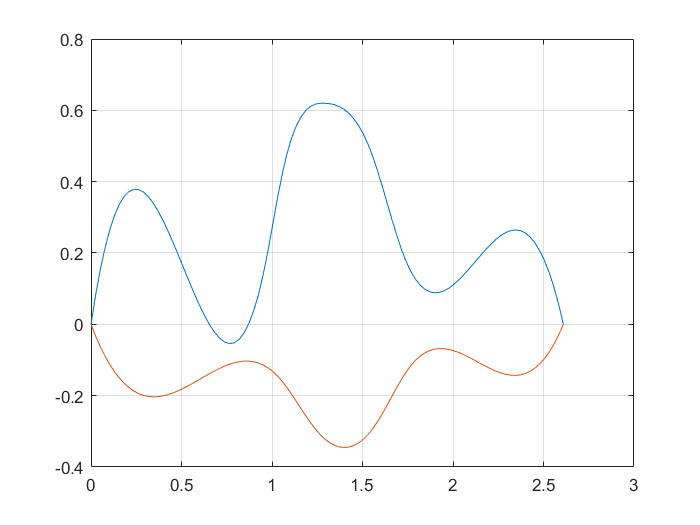

xdptop = [0 0.51 0.96 1.06 1.29 1.55 1.73 2.13 2.61];
ydptop = [0 0.16 0.16 0.43 0.62 0.48 0.19 0.18 0];
x = linspace(0, 2.61, 100);

xdpbottom = [0 0.58 1.04 1.25 1.56 1.76 2.19 2.61];
ydpbottom = [0 -0.16 -0.15 -0.30 -0.29 -0.12 -0.12 0];

clf
plot(x, interp1(xdptop, ydptop, x, 'spline'))
grid on, hold on
plot(x, interp1(xdpbottom, ydpbottom, x, 'spline'))

## Problem 3.)

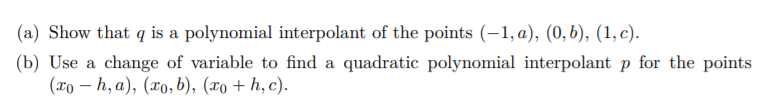

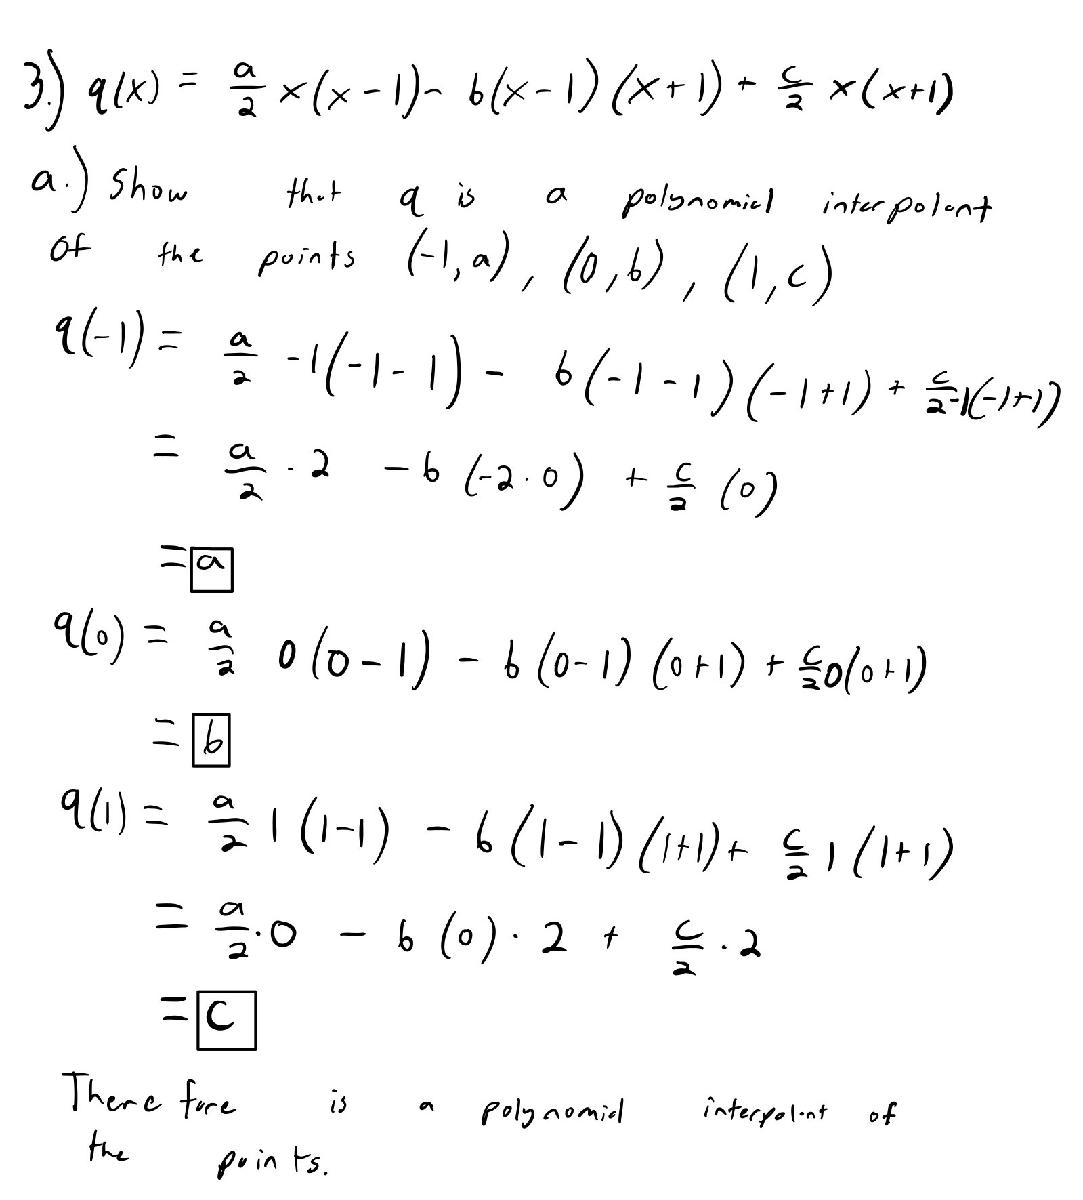

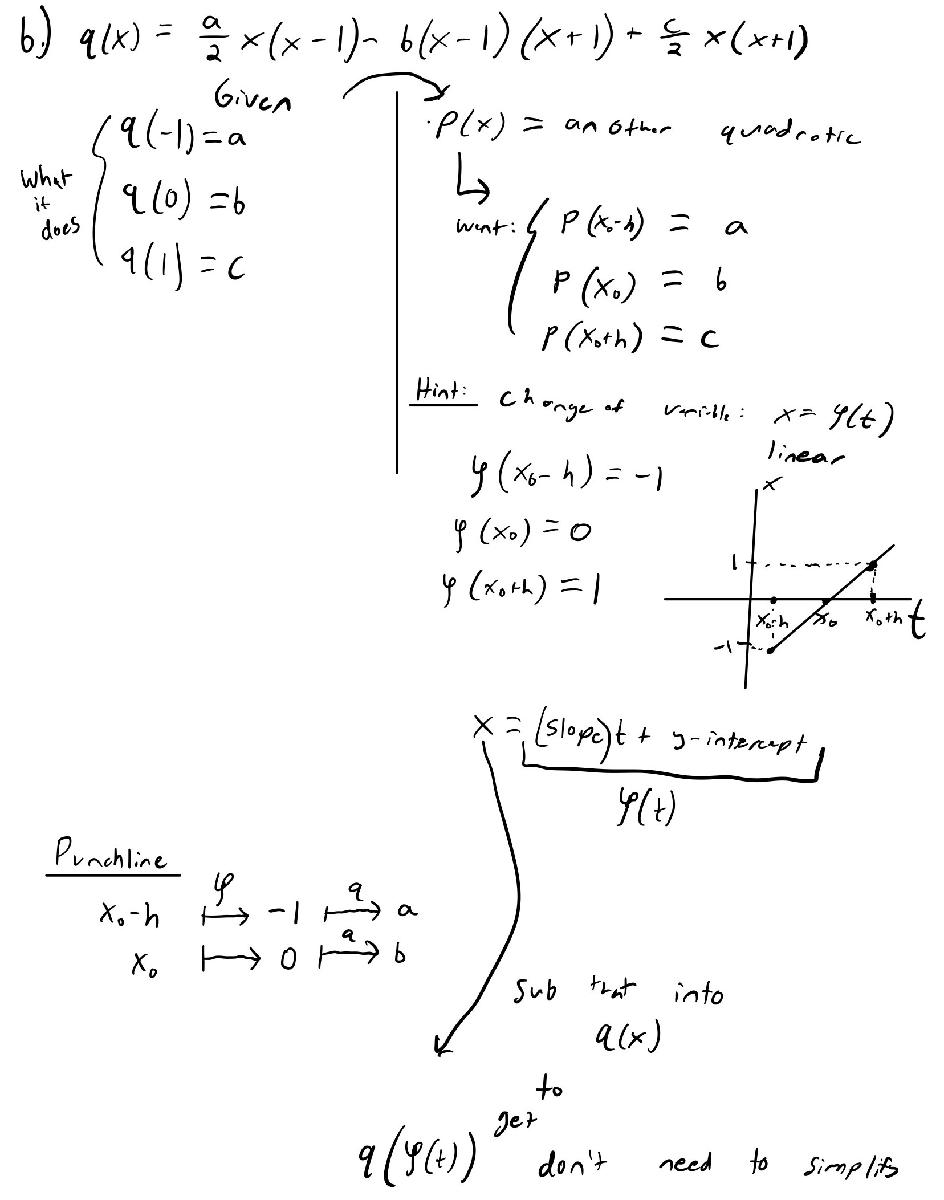

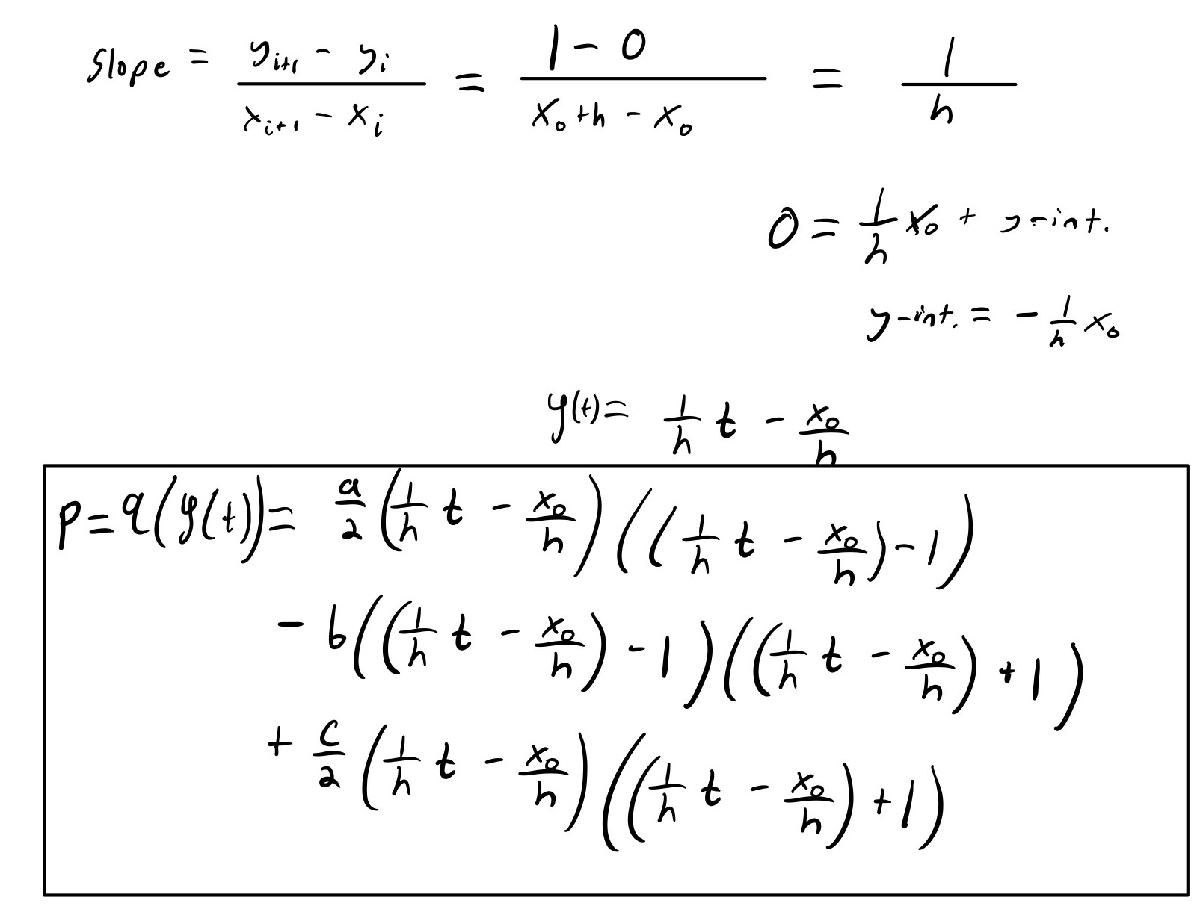

## Problem 4.)

t = [0 0.075 0.25 0.55 1]';
x = linspace(0,1,100);
y = eye(5);

ydp = y(:,1)';
ydp

ydp =      1     0     0     0     0


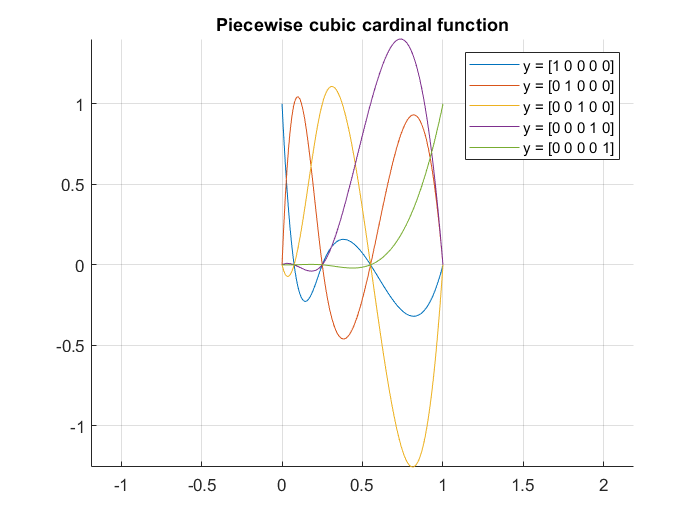

clf
hold on
plot(x, interp1(t, ydp, x, 'spline'))
grid on, axis equal
hold on
title('Piecewise cubic cardinal function')

ydp = y(:,2)';
plot(x, interp1(t, ydp, x, 'spline'))
ydp = y(:,3)';
plot(x, interp1(t, ydp, x, 'spline'))
ydp = y(:,4)';
plot(x, interp1(t, ydp, x, 'spline'))
ydp = y(:,5)';
plot(x, interp1(t, ydp, x, 'spline'))
legend('y = [1 0 0 0 0]', 'y = [0 1 0 0 0]', 'y = [0 0 1 0 0]', 'y = [0 0 0 1 0]', 'y = [0 0 0 0 1]')

## Problem 5.)

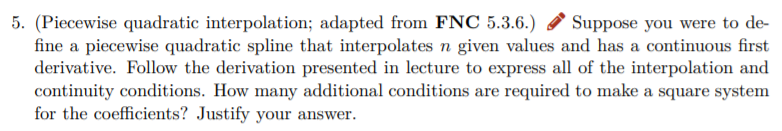

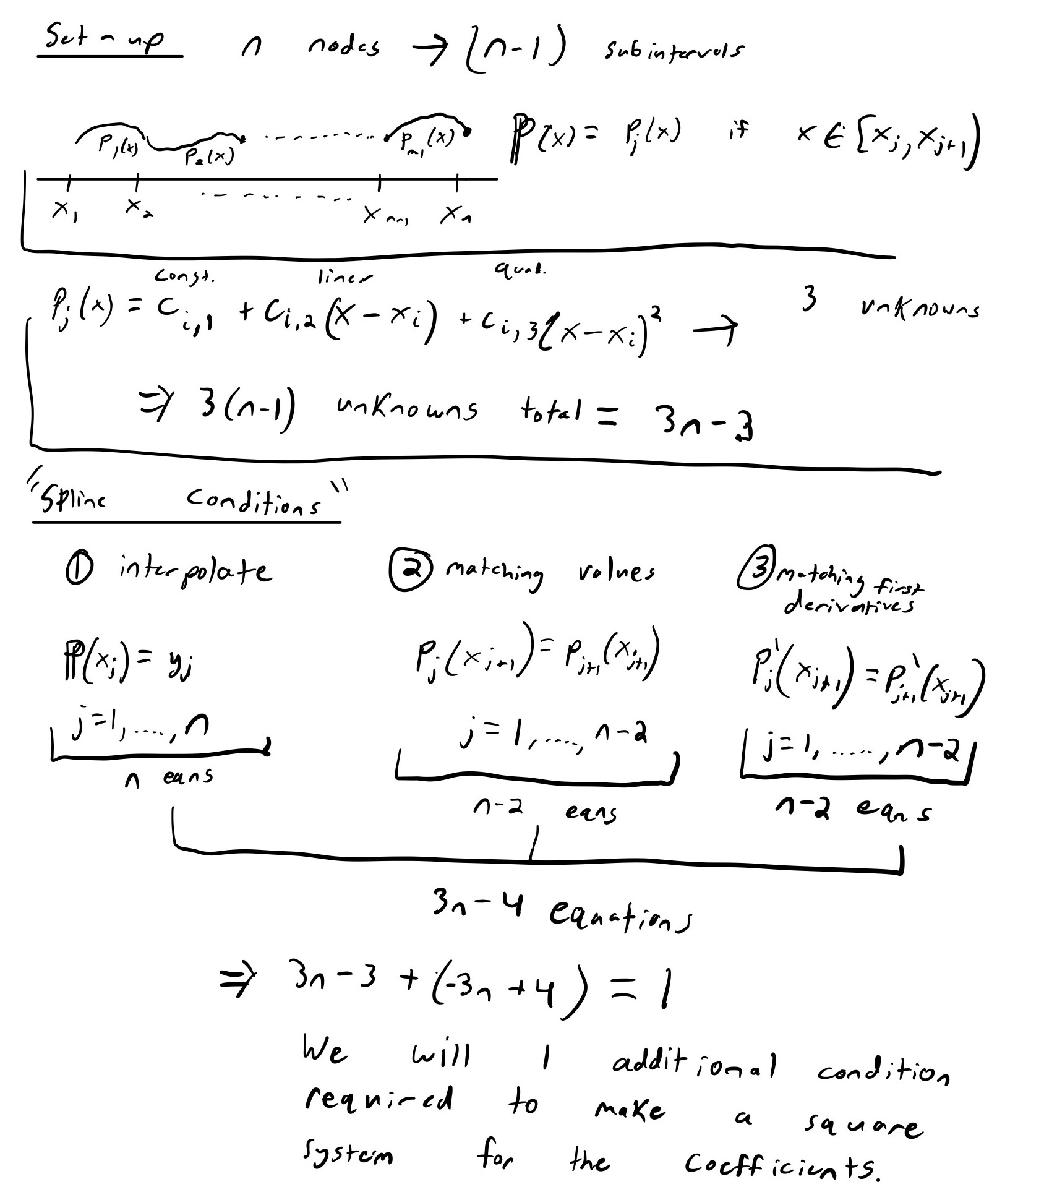

## Problem 6.)

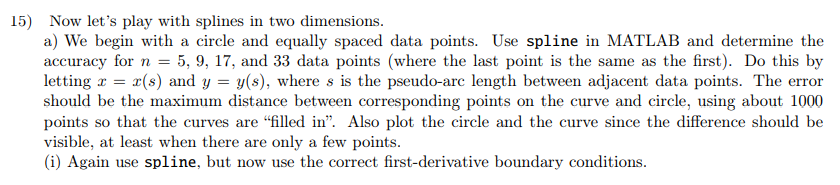

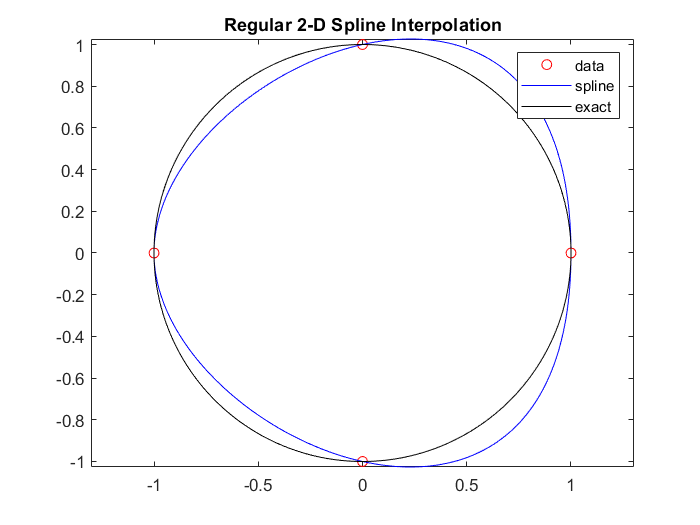

%To find error find the max error over the entire approx. circle and actual
%circle using sqrt((xactual - xapprox)^2 + (yactual - yapprox.)^2)

n = 5;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('Regular 2-D Spline Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.1815

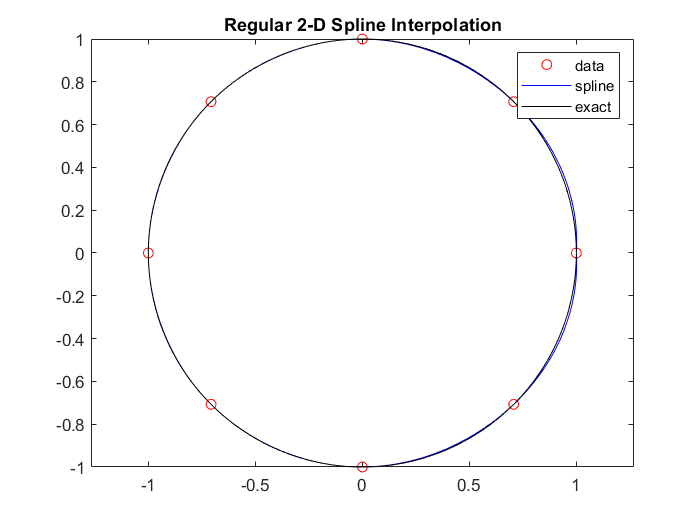


n = 9;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('Regular 2-D Spline Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.0106

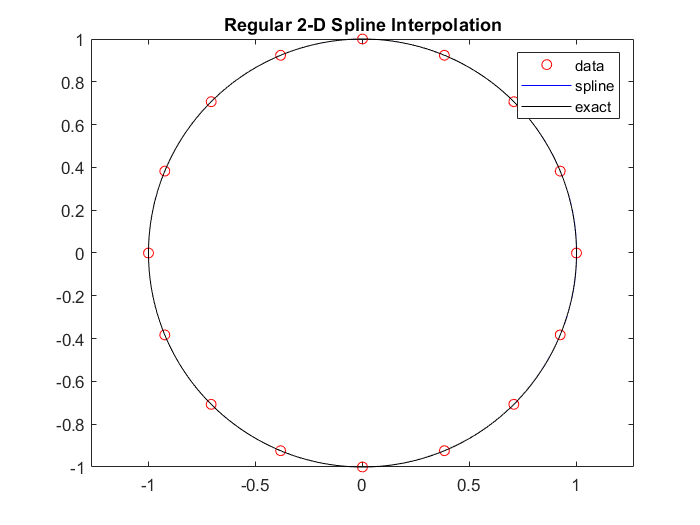


n = 17;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('Regular 2-D Spline Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 6.7032e-04

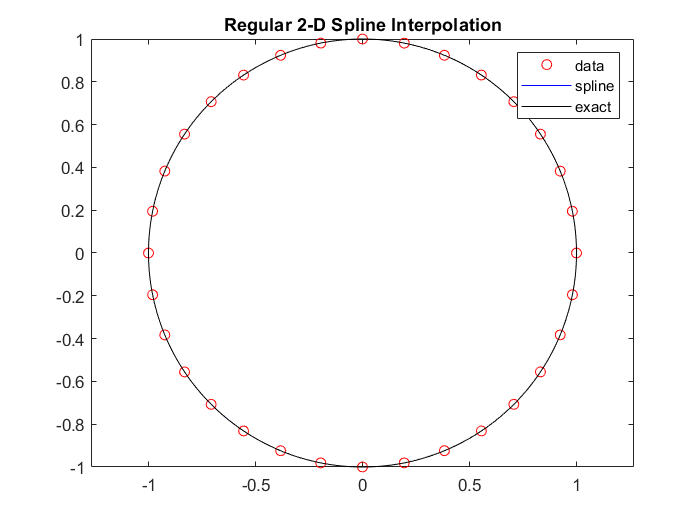


n = 33;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('Regular 2-D Spline Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 4.1942e-05

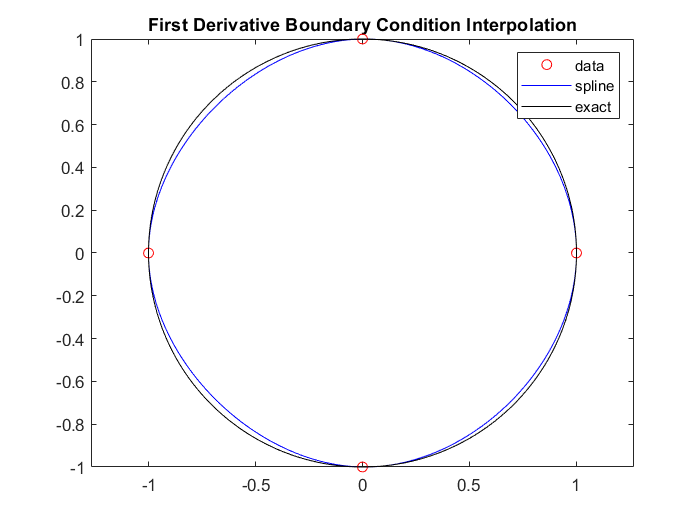


n = 5;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);
fxprime = @(theta) -sin(theta);
fyprime = @(theta) cos(theta);

tdp = linspace(0, 2*pi, n)';
xdp = [fxprime(tdp(1)); fx(tdp); fxprime(tdp(end))];
ydp = [fyprime(tdp(1)); fy(tdp); fyprime(tdp(end))];

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('First Derivative Boundary Condition Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.0305

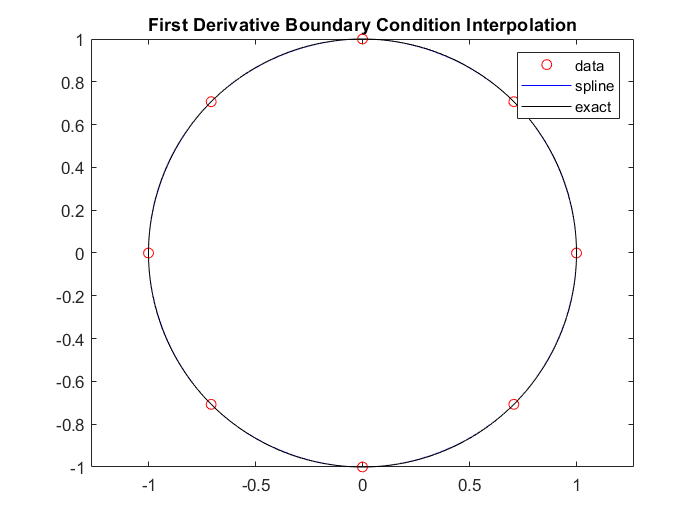


n = 9;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);
fxprime = @(theta) -sin(theta);
fyprime = @(theta) cos(theta);

tdp = linspace(0, 2*pi, n)';
xdp = [fxprime(tdp(1)); fx(tdp); fxprime(tdp(end))];
ydp = [fyprime(tdp(1)); fy(tdp); fyprime(tdp(end))];

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('First Derivative Boundary Condition Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.0012

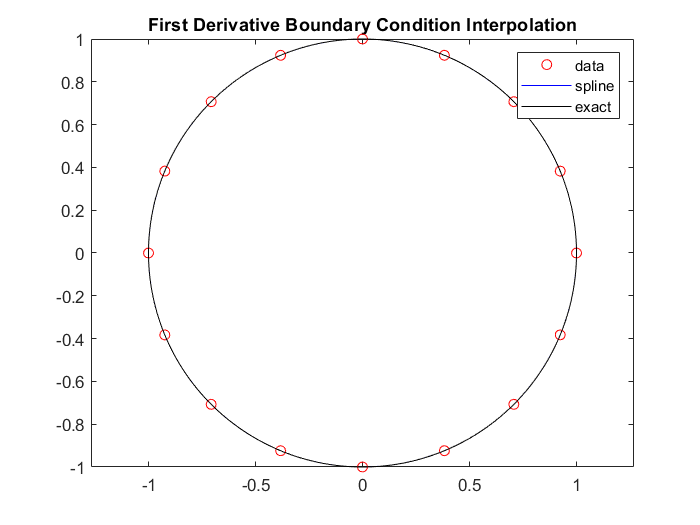


n = 17;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);
fxprime = @(theta) -sin(theta);
fyprime = @(theta) cos(theta);

tdp = linspace(0, 2*pi, n)';
xdp = [fxprime(tdp(1)); fx(tdp); fxprime(tdp(end))];
ydp = [fyprime(tdp(1)); fy(tdp); fyprime(tdp(end))];

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('First Derivative Boundary Condition Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 6.5596e-05

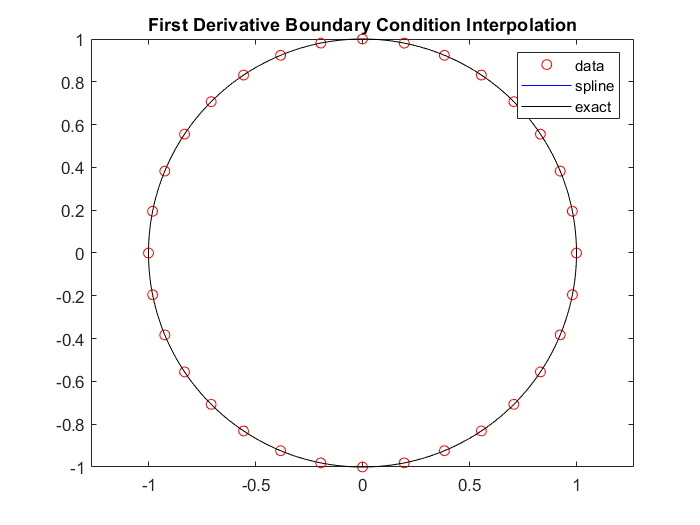


n = 33;
fx = @(theta) cos(theta);
fy = @(theta) sin(theta);
fxprime = @(theta) -sin(theta);
fyprime = @(theta) cos(theta);

tdp = linspace(0, 2*pi, n)';
xdp = [fxprime(tdp(1)); fx(tdp); fxprime(tdp(end))];
ydp = [fyprime(tdp(1)); fy(tdp); fyprime(tdp(end))];

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')
title('First Derivative Boundary Condition Interpolation')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 3.9276e-06

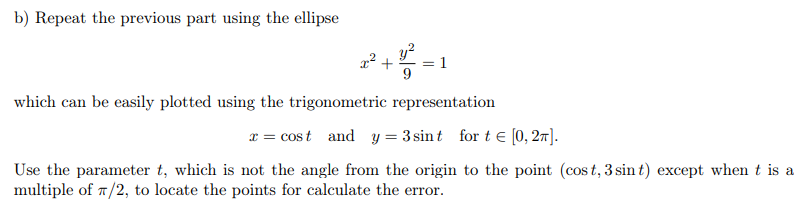

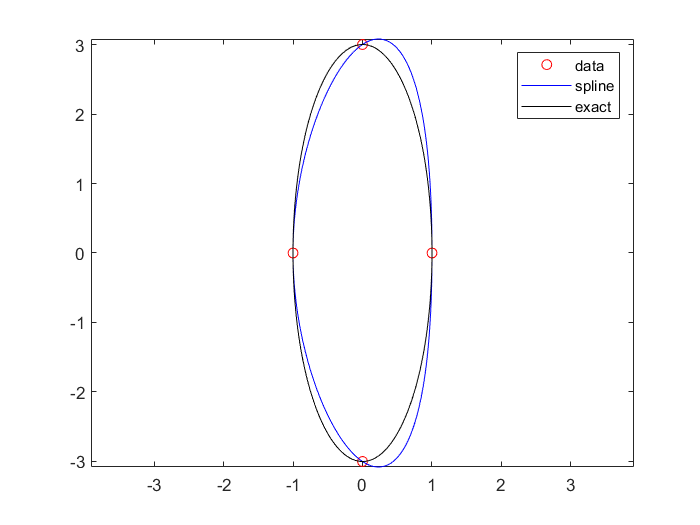

n = 5;
fx = @(theta) cos(theta);
fy = @(theta) 3*sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.5425

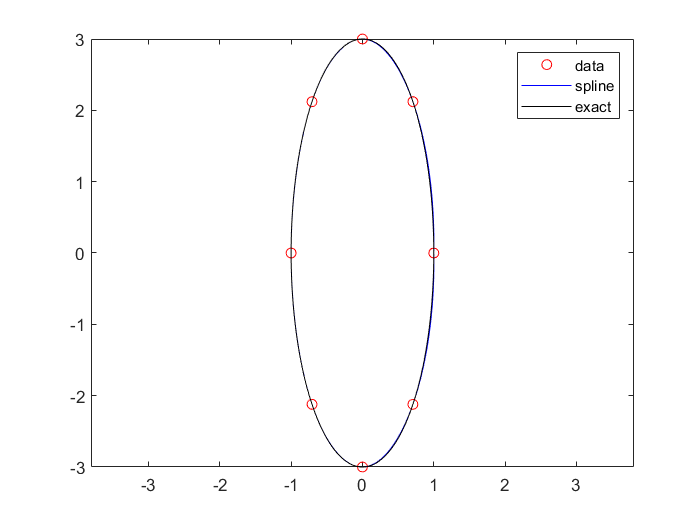


n = 9;
fx = @(theta) cos(theta);
fy = @(theta) 3*sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.0244

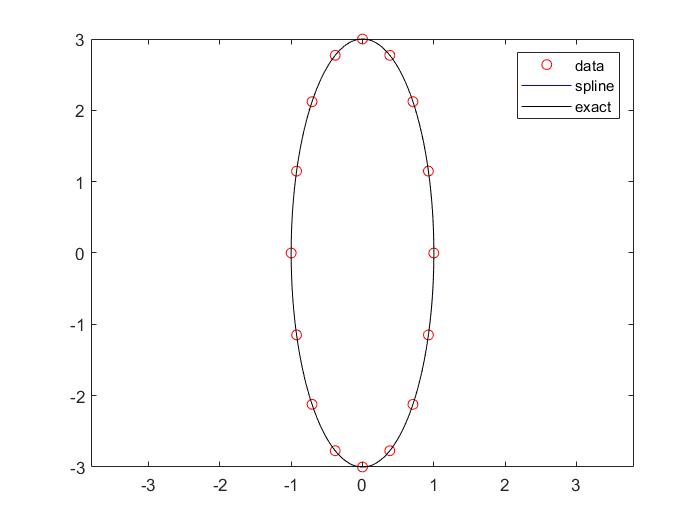


n = 17;
fx = @(theta) cos(theta);
fy = @(theta) 3*sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 0.0010

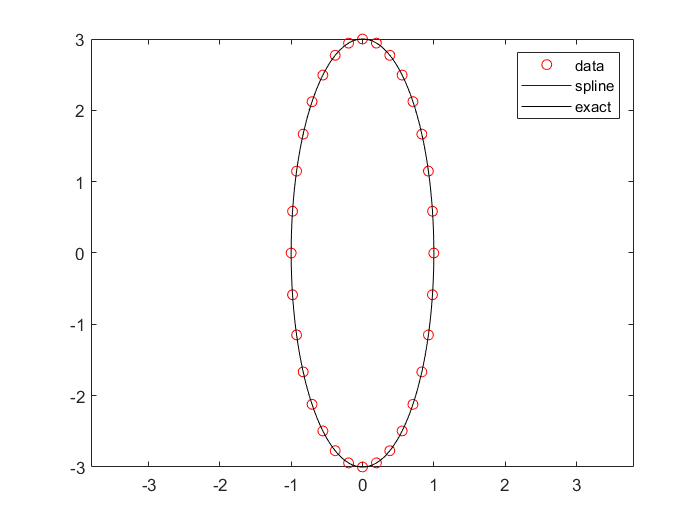


n = 33;
fx = @(theta) cos(theta);
fy = @(theta) 3*sin(theta);

tdp = linspace(0, 2*pi, n)';
xdp = fx(tdp);
ydp = fy(tdp);

%interpolation
t = linspace(0, 2*pi, 1000)';
x = spline(tdp, xdp, t);
y = spline(tdp, ydp, t);

clf
plot(xdp, ydp, 'ro'), hold on
axis equal
plot(x, y, 'b')
plot(fx(t), fy(t), 'k')
legend('data', 'spline', 'exact')

error = max(sqrt((fx(t) - x).^2 + (fy(t) - y).^2))

error = 4.8214e-05